t = 0:1/1024:1;
x = sin(2*pi*60*t) + sin(2*pi*120*t);
y = hilbert(x);

plot(t(1:50),real(y(1:50)))
hold on
plot(t(1:50),imag(y(1:50)))
hold off
axis([0 0.05 -1.1 2])
legend('Real Part','Imaginary Part')

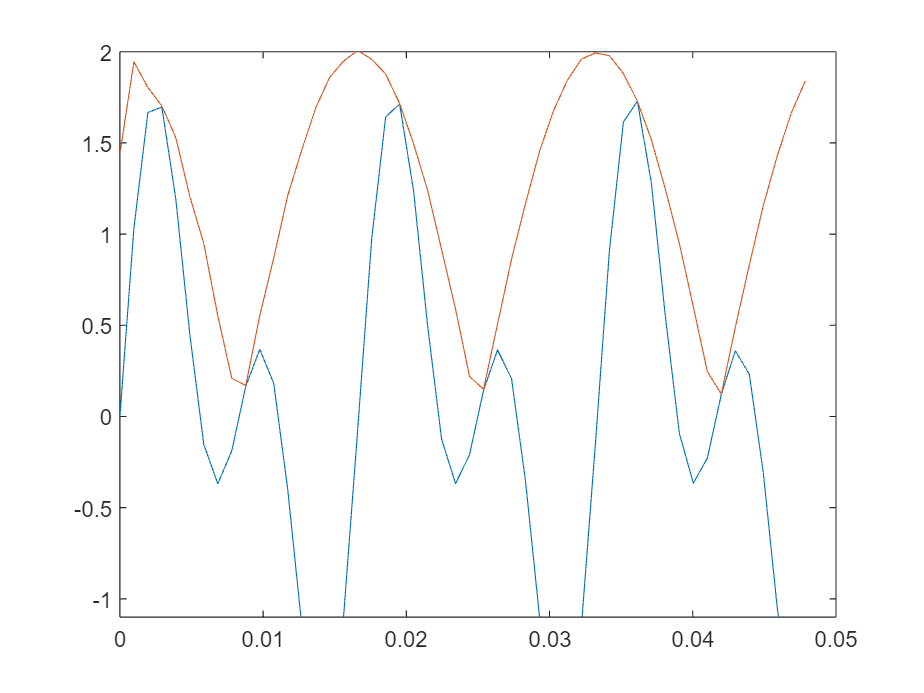

plot(t(1:50), x(1:50))
hold on
plot(t(1:50), abs(y(1:50)))
axis([0 0.05 -1.1 2])

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector

S = 0.8 + 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);

X = S + 2*randn(size(t));

Y = fft(X);

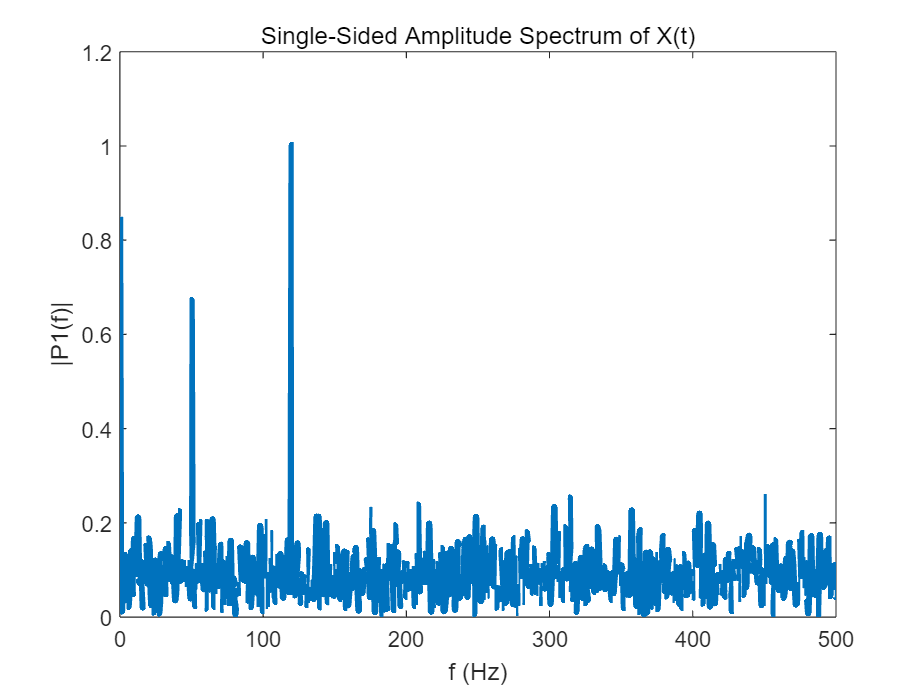

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs/L*(0:(L/2));
plot(f,P1,"LineWidth",3) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")